## Rete Anticipatrice

Definizione del **numeratore** e del **denominatore** della **FdT P(s)**.

num = 99;
den = conv([0.001 1],conv([1 1],[0.1 1]));

P_s = tf(num,den)


P_s =
 
                   99
  -------------------------------------
  0.0001 s^3 + 0.1011 s^2 + 1.101 s + 1
 
Continuous-time transfer function.
Model Properties


Determinare una **rete correttrice** affinchè:

- **Pulsazione di attraversamento**: wt > 70 [rad/s]

- **Margine di fase**: mf > 40°

Calcolo del **Margine di Guadagno** e** di Fase **della funzione **P(s)**.

- Dal diagramma si nota che nessuno dei due requisti è soddisfatto.

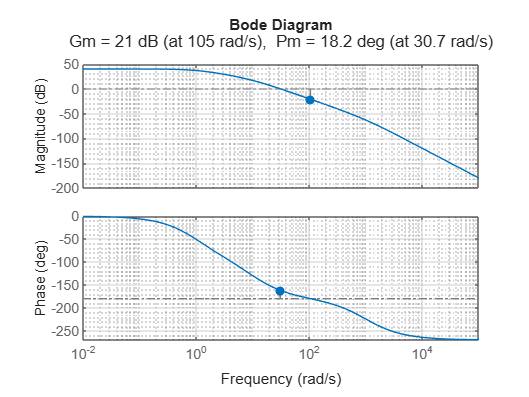

margin(P_s)
grid on
grid minor

**Rete correttrice.**

- Una possibile soluzione è l'introduzione di una **Rete anticipatrice** per aumentare sia il **margine di fase** che la **pulsazione di attraversamento**.

K = 10;
alfa = 10;
tau = 0.01;

num = (K/alfa)*[alfa*tau 1];
den = [tau 1];

G_s = tf(num,den);

**Funzione ad anello aperto complessiva F(s).**

- **F(s) = G(s)P(s).**

- Dal diagramma si nota che entrambi i requisiti sono soddisfatti.

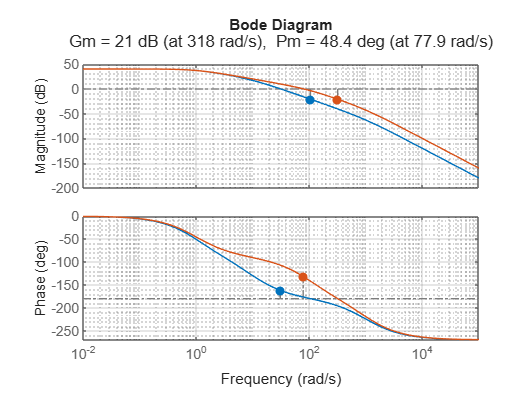

F_s = G_s*P_s;

hold on
margin(F_s)
grid on
grid minor
hold off